%% Initialize Data
clc;
clear all;
close all;
projectData = load("projectData26.mat");
time = projectData.timeData;
waterflow = projectData.waterflowData;
waterflowData = iddata(waterflow);
%sarimaWorkbench(waterflowData);

lags = 40;
trainingEnd = floor(length(waterflow)*0.8); 

period = 365; %Guess from data


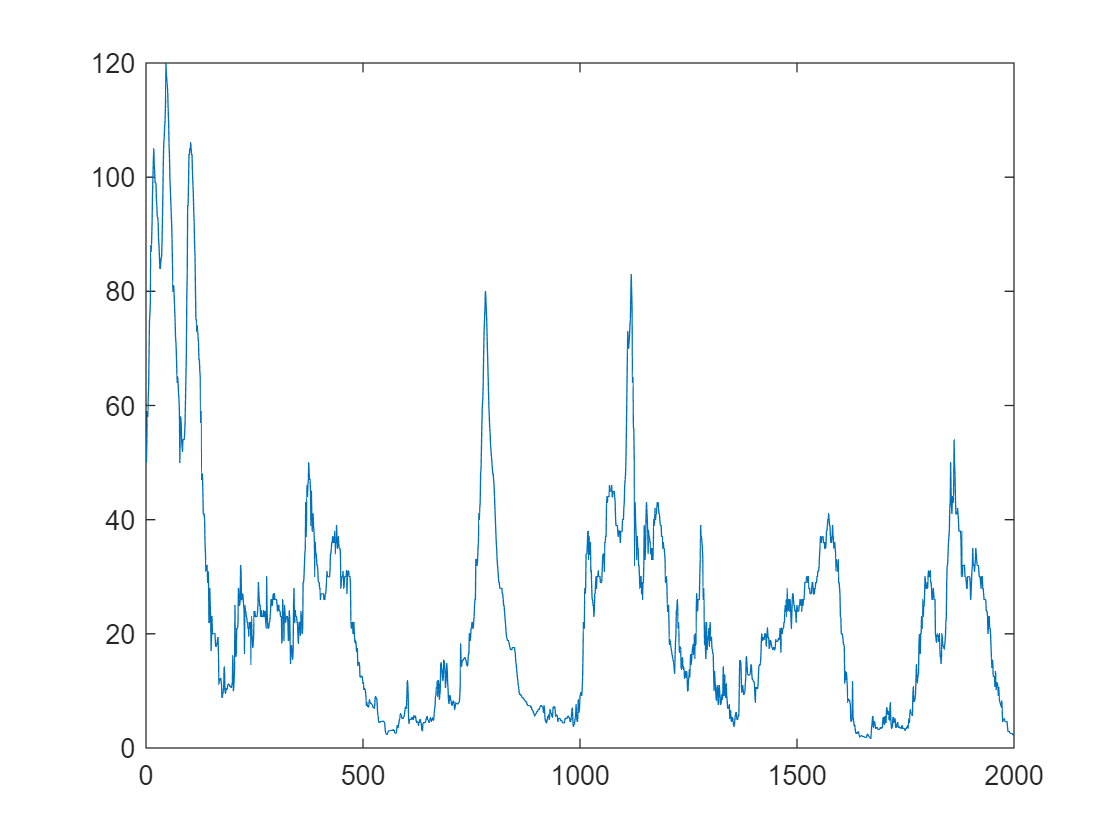


%%
plot(waterflow)

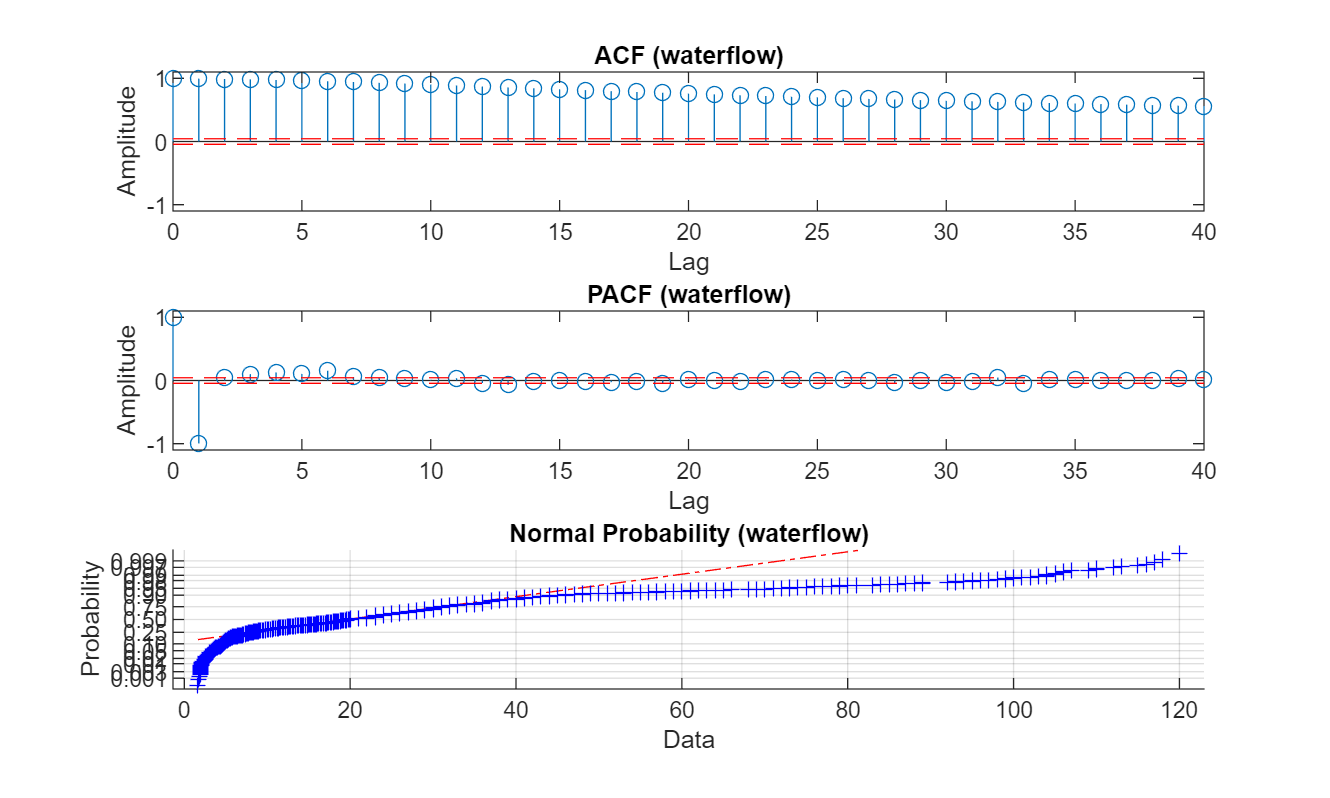


aaACFPACFN(waterflowData.OutputData, lags, "waterflow", 0.05);

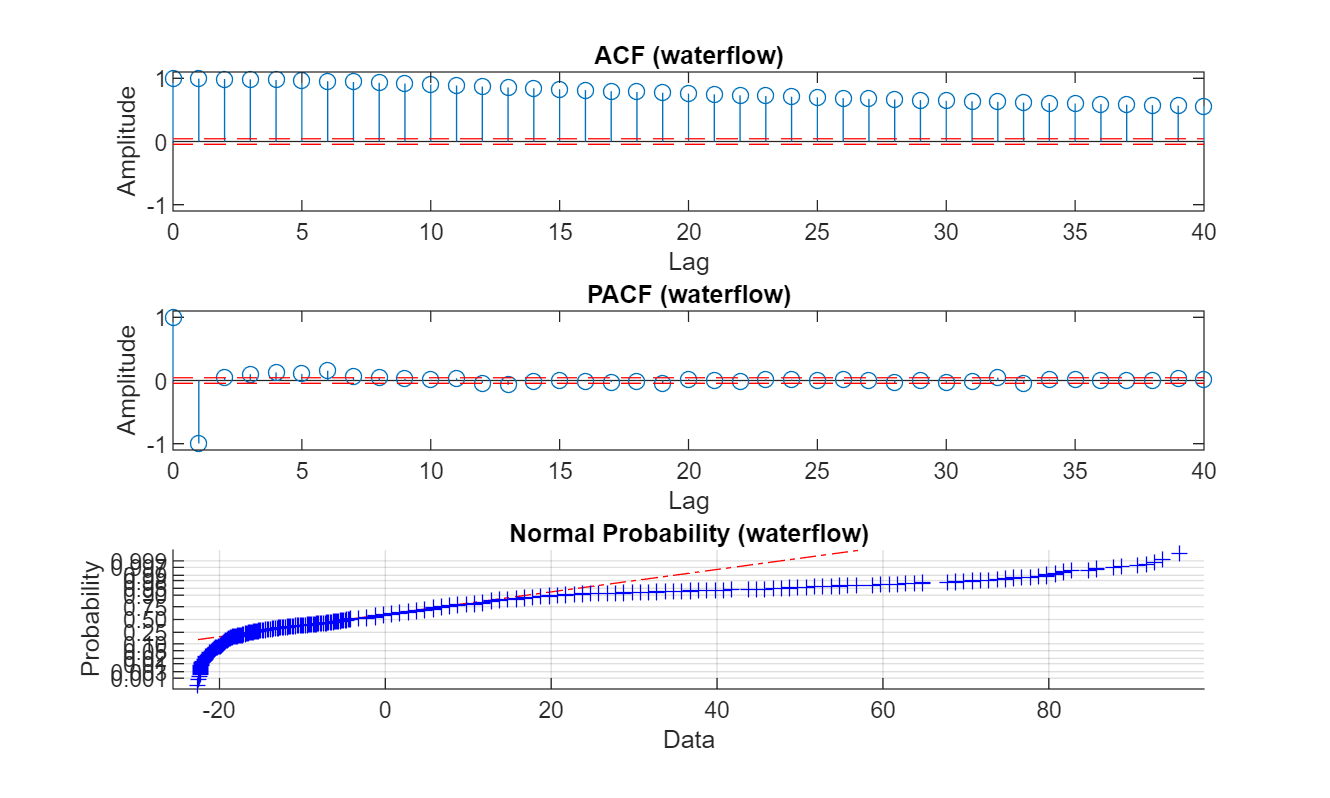


%%  Plot data

waterflowDataZeroMean = iddata(waterflowData.OutputData - mean(waterflowData.OutputData));

aaACFPACFN(waterflowDataZeroMean.OutputData, lags, "waterflow", 0.05);

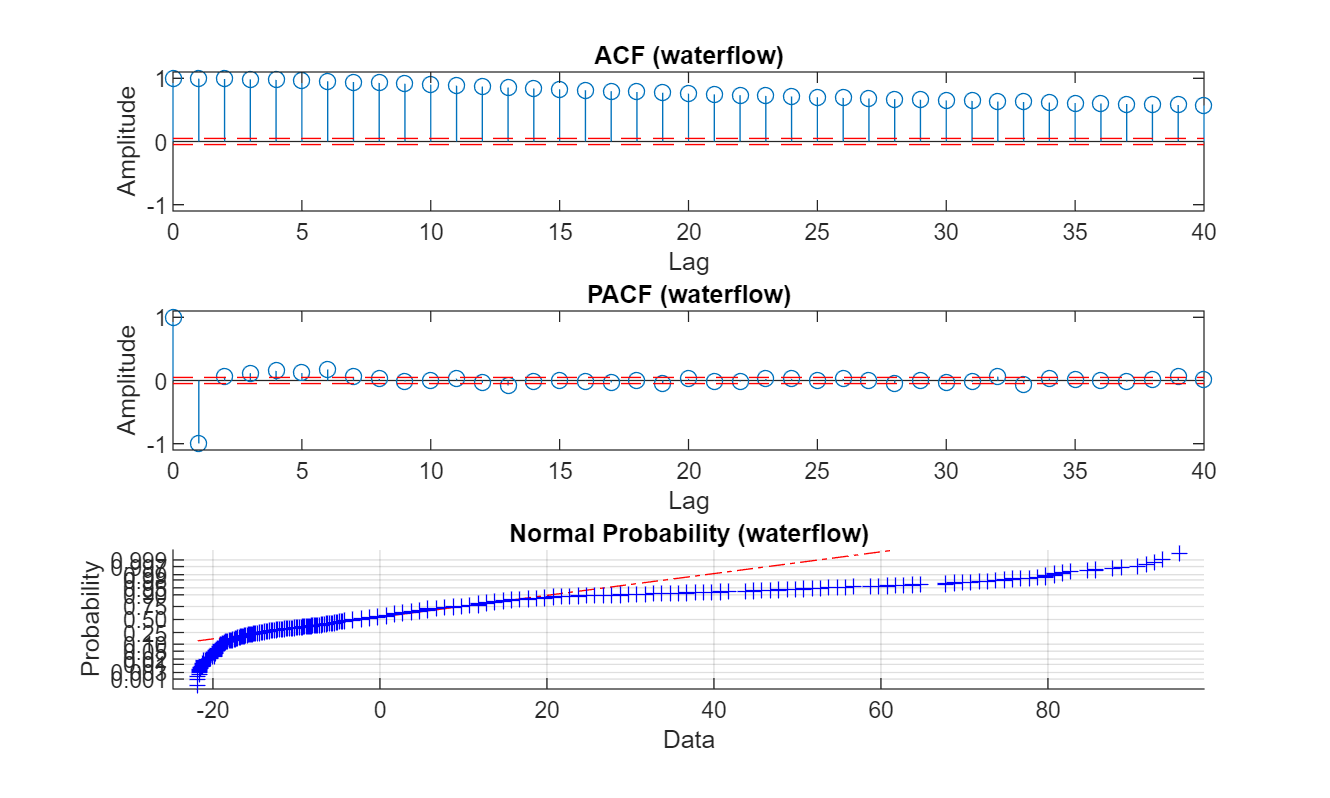


%% Extract training period
waterflowTrainingData =waterflowDataZeroMean(1: trainingEnd);

aaACFPACFN(waterflowTrainingData.OutputData, lags, "waterflow", 0.05);

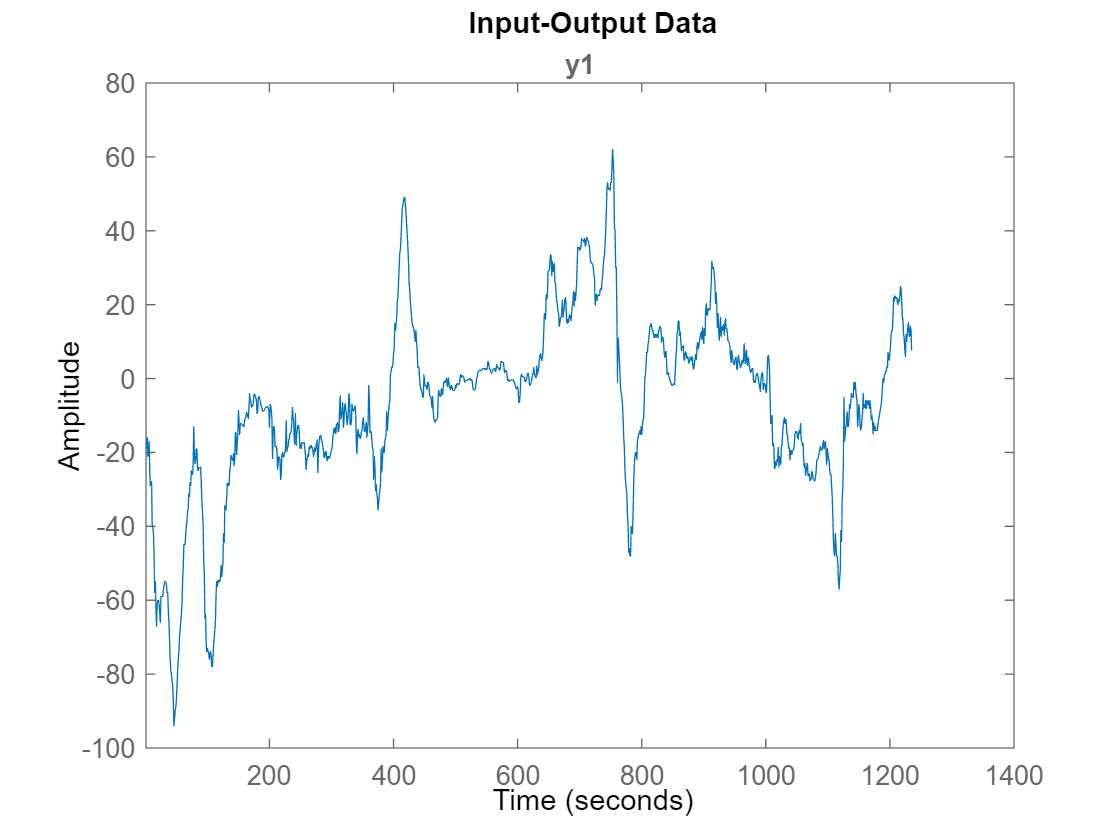


%%Apply period to the data
A365 = [1 zeros(1,364) -1];

WFTDNoSeason = filter(A365, 1, waterflowTrainingData.OutputData);
WFTDNoSeason = WFTDNoSeason(length(A365):end);
WFTDNoSeason = iddata(WFTDNoSeason);

figure;
plot(WFTDNoSeason)

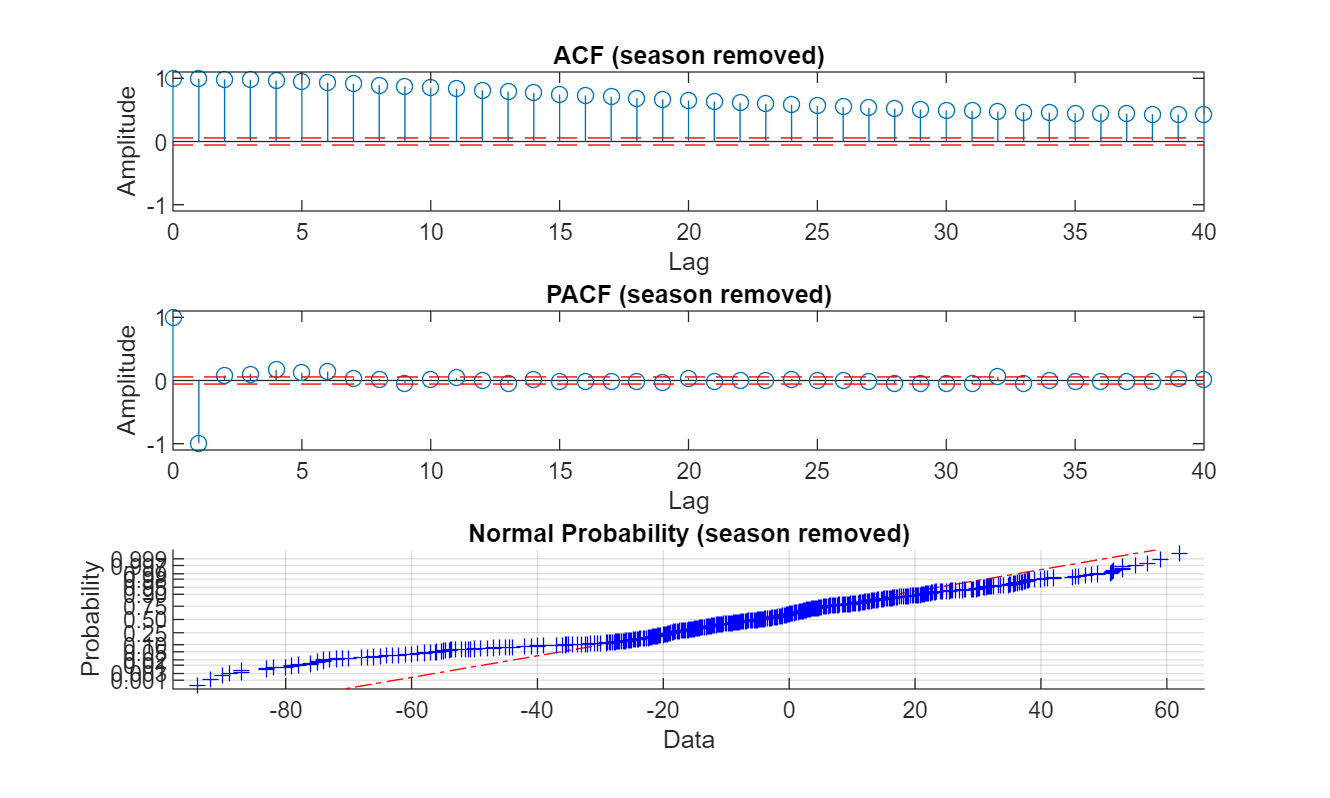

figure;
aaACFPACFN(WFTDNoSeason.OutputData, 40, "season removed",0.05);



%% Create Model
modelinit = idpoly([1 0], [], []);
% modelinit3.Structure.a.Free = [1 1 1 zeros(1,7) 1 1 zeros(1,11) 1 1];
mod1 = pem(WFTDNoSeason, modelinit);

present(mod1)

                                                                              
mod1 =                                                                        
Discrete-time AR model: A(z)y(t) = e(t)                                       
  A(z) = 1 - 0.9933 (+/- 0.003288) z^-1                                       
                                                                              
Sample time: 1 seconds                                                        
                                                                              
Parameterization:                                                             
   Polynomial orders:   na=1                                                  
   Number of free coefficients: 1                                             
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.
                                                                              
Status:                                             

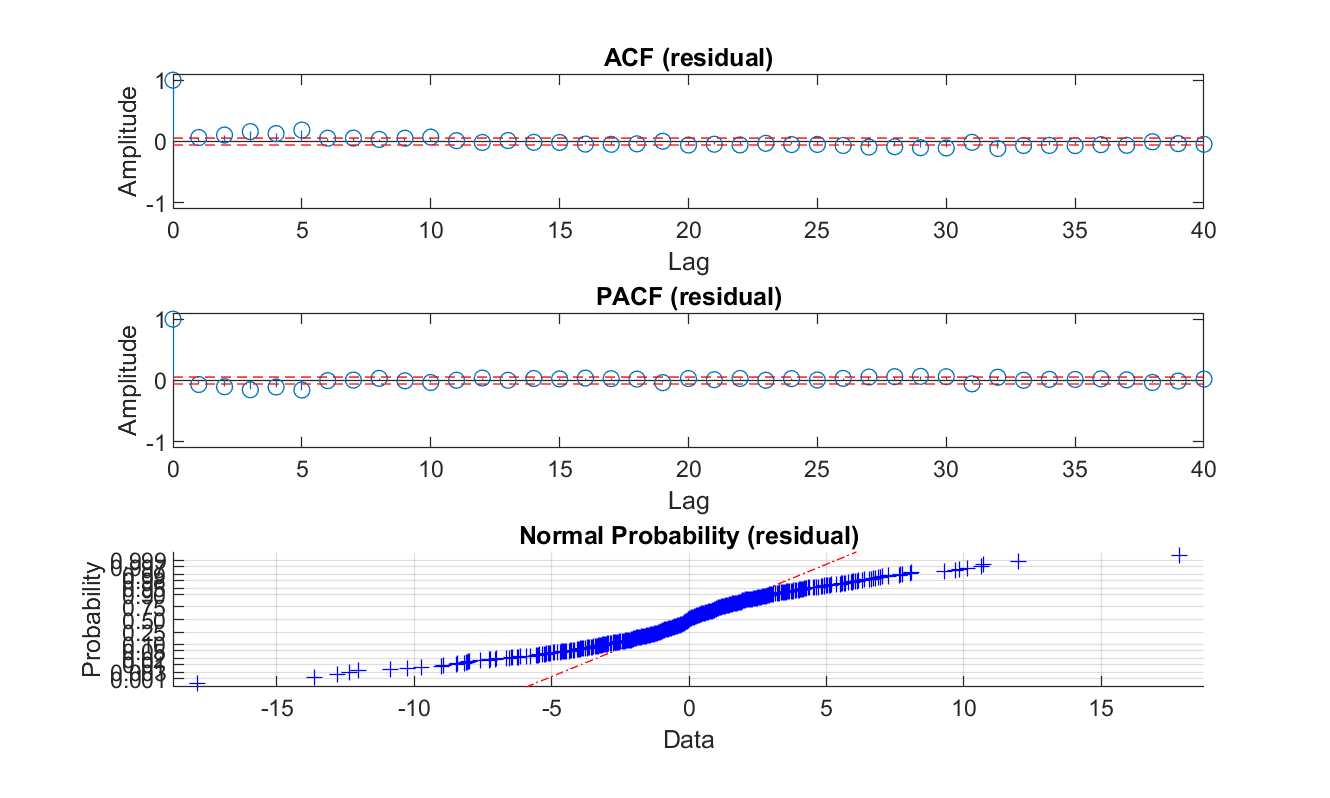


e_hat = aaFilter(mod1.a,mod1.c,WFTDNoSeason.OutputData,lags);

aaACFPACFN(e_hat, lags, "residual", 0.05);

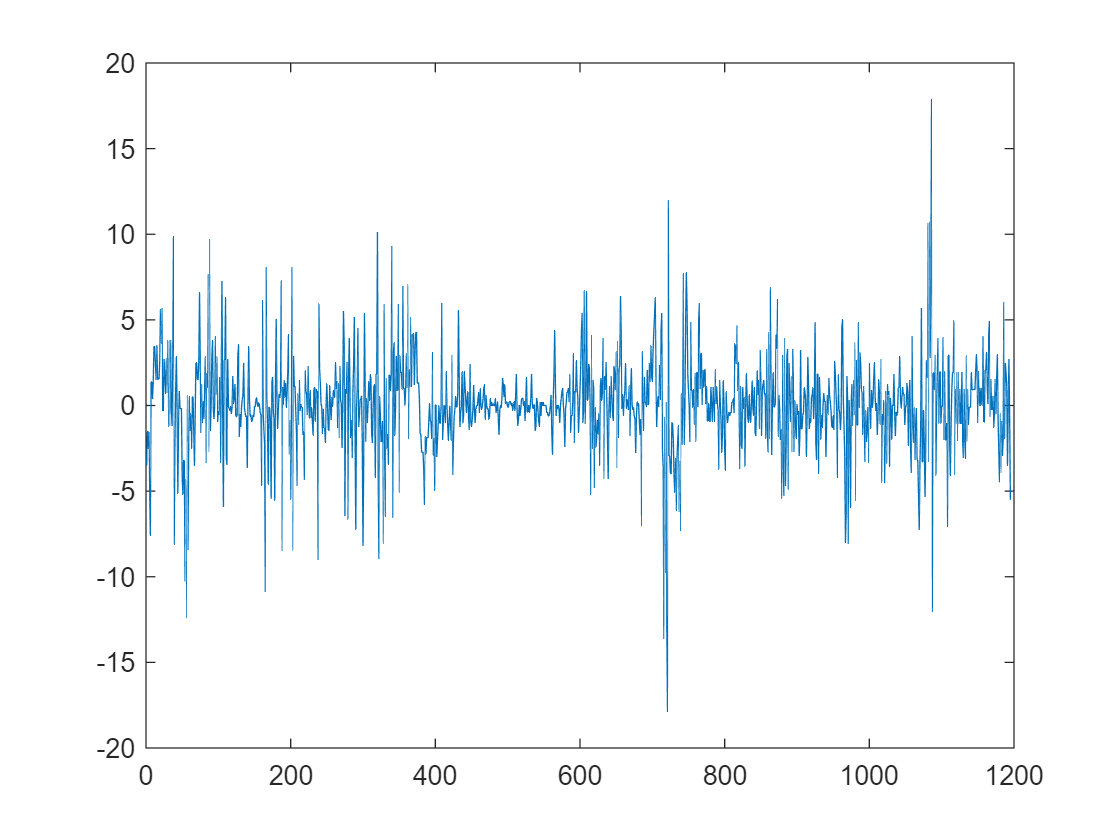


figure
plot(e_hat)

%% Model Step
modelinit = idpoly([1 0 0 0 0 0], [], [1 zeros(1,365)]);
modelinit.Structure.c.Free = [1 0 0 0 0 1 zeros(1,359) 1];
modelinit.Structure.a.Free = [1 1 0 0 0 1];
mod2 = pem(WFTDNoSeason, modelinit);

present(mod2)

                                                                              
mod2 =                                                                        
Discrete-time ARMA model: A(z)y(t) = C(z)e(t)                                 
  A(z) = 1 - 1.071 (+/- 0.01712) z^-1 + 0.0903 (+/- 0.01705) z^-5             
                                                                              
  C(z) = 1 + 0.1559 (+/- 0.03434) z^-5 - 0.39 (+/- 0.02874) z^-365            
                                                                              
Sample time: 1 seconds                                                        
                                                                              
Parameterization:                                                             
   Polynomial orders:   na=5   nc=365                                         
   Number of free coefficients: 4                                             
   Use "polydata", "getpvec", "getcov" for parameter

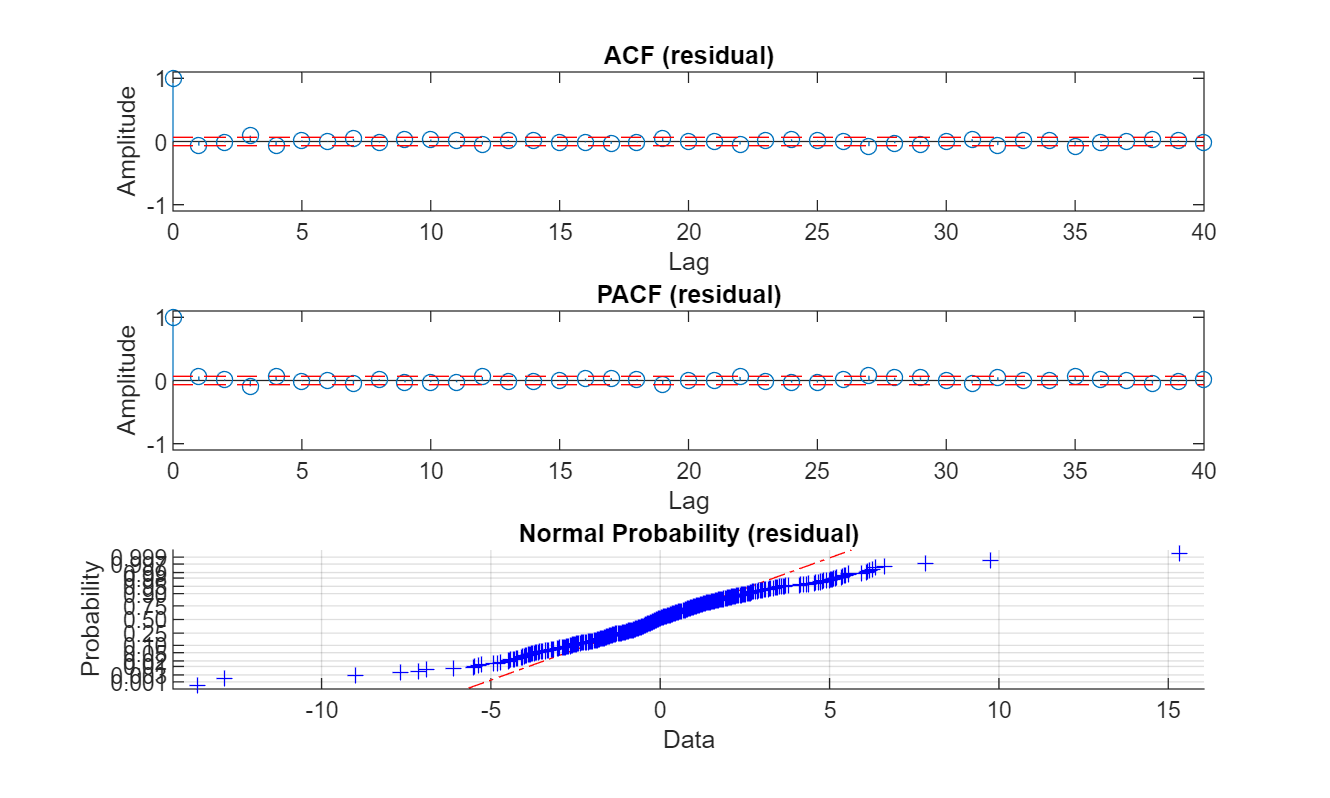


e_hat = aaFilt(mod2.a,mod2.c,WFTDNoSeason.OutputData);

aaACFPACFN(e_hat, lags, "residual", 0.05);

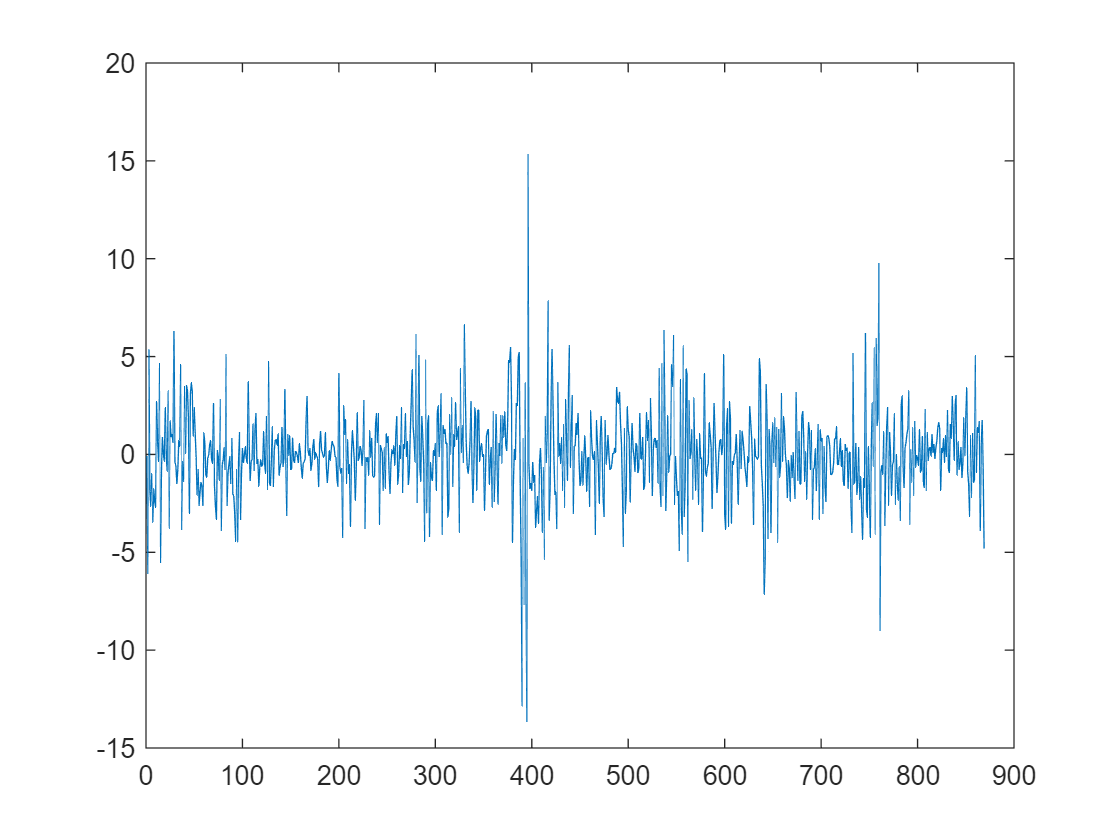


figure
plot(e_hat)

## Add back the season

mod2.a = conv(mod2.a, A365);

## Save model

save("myData.mat");


## Load model

load("myData.mat");


## Create the predictors for k = 1,15, 30

k = [1 15 30];

y_hat_3 = aaPredict(waterflowData.OutputData, mod2.c,mod2.a,k(1));



## Plot the output prediction and compare to the validation data.

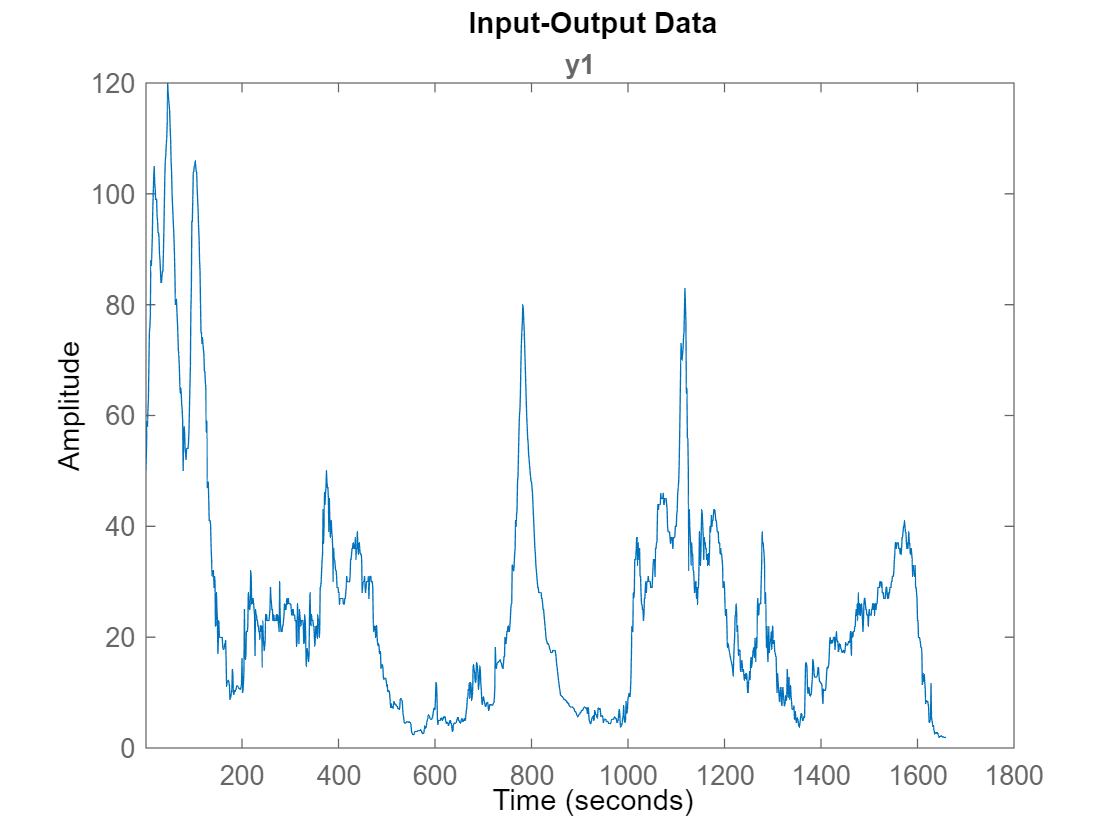


pstart = length(waterflowTrainingData.OutputData);
kMax = 2*30;

f1 = figure;
indV = pstart:pstart+kMax-1;
plot([waterflowData(1:pstart+kMax-1)])
%xlim([pstart-30 pstart+kMax])
hold on

plot(indV, y_hat_3(indV))

Index exceeds the number of array elements. Index must not exceed 1634.

indV = pstart-1:pstart+kMax-1;
% plot( indV, pred_yk(indV) + 2*sqrt(var_yk(indV)),'b:' )
% plot( indV, pred_yk(indV) - 2*sqrt(var_yk(indV)),'b:' )
figProp = get(f1);
line( [pstart pstart], figProp.CurrentAxes.YLim, 'Color', 'red', 'LineStyle', ':' )
hold off
legend('Output data', 'Predicted output', 'Prediction starts','Location','NW')
title( 'Predicting the output for k=1')
xlabel('Time')

